# Lab - Initial value problems 3

Last modified by Dr. Xu 6/27/2022

**Topics: **Stiff systems

## Initial values

clear, clc, format compact


$$y_1 \left(0\right)=\frac{{\textrm{dy}}_1 }{\textrm{dt}}\left(0\right)=1$$


y0 = [1 1];

## ode45 mu = 1, t = 0 to 60

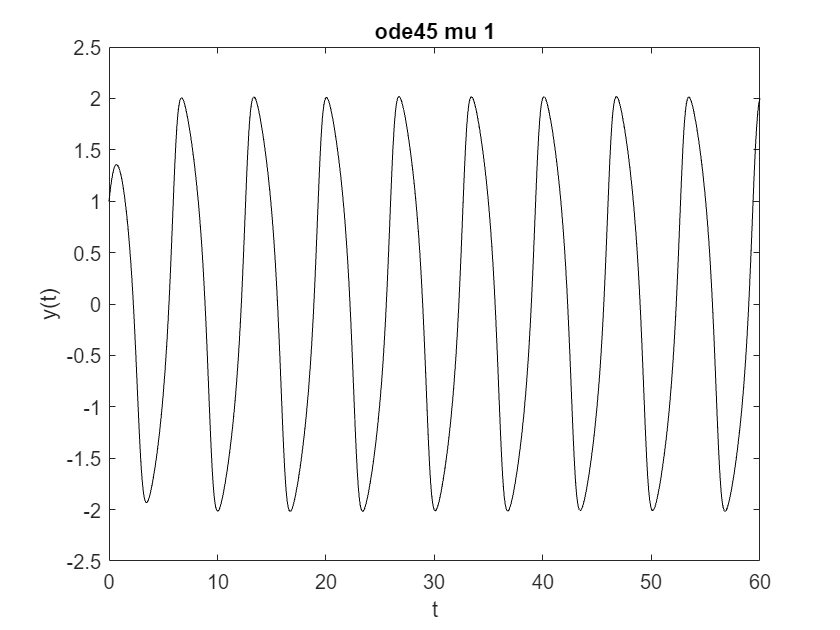

mu = 1;
[t,y] = ode45(@vanDerPol, [0 60], y0, [], mu);
plot(t,y(:,1),'k')
xlabel 't'
ylabel 'y(t)'
title 'ode45 mu 1'

## ode45 mu = 1000, t = 0 to 6000

% mu = 1000;
% [t,y] = ode45(@vanDerPol, [0 6000], y0, [], mu);
% plot(t,y(:,1),'k')
% xlabel 't'
% ylabel 'y(t)'
% title 'ode45 mu 1000'
% code fails

## ode23s mu = 1000, t = 0 to 6000

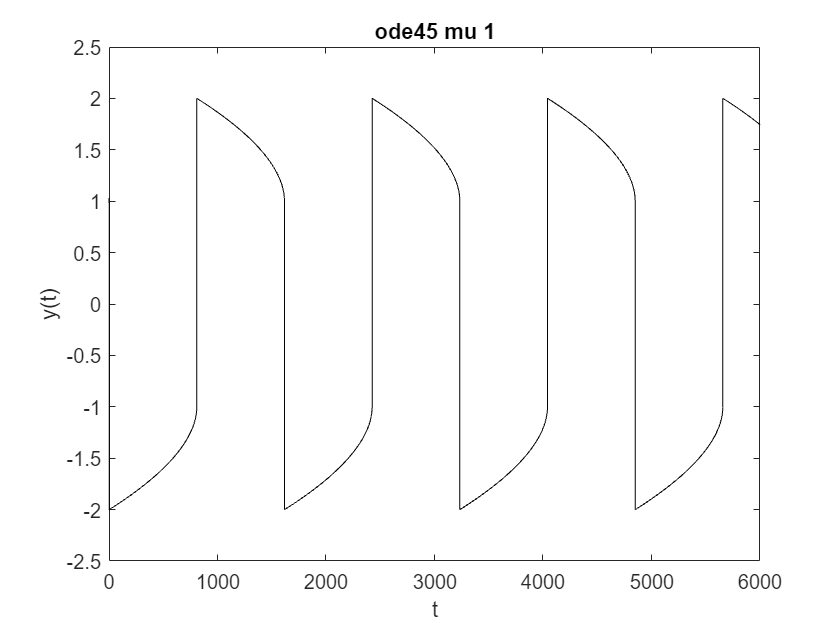

mu = 1000;
[t,y] = ode23s(@vanDerPol, [0 6000], y0, [], mu);
plot(t,y(:,1),'k')
xlabel 't'
ylabel 'y(t)'
title 'ode23s mu 1000'

## Helper functions


$$\frac{d}{\textrm{dt}}\left\lbrack Y\right\rbrack =\left\lbrack \begin{array}{c}
Y\left(2\right)\\
\mu \left(1-{Y\left(1\right)}^2 \right)Y\left(2\right)-Y\left(1\right)
\end{array}\right\rbrack$$


function dY = vanDerPol(t,Y,mu)

dY = [Y(2);mu*(1-Y(1)^2)*Y(2)-Y(1)];

end
